#                          ARIMA and Monte-Carlo on Erzincan Radon data 

Script for importing data from the following spreadsheet:

## Setup the Import Options

opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:B2002";

% Specify column names and types
opts.VariableNames = ["Date", "Rn222Bqm3"];
opts.VariableTypes = ["datetime", "double"];

% Import the data
tbl = readtable("C:\Users\MM\Desktop\peoples work\mustafa khairi\Radon Data for MUSTAFA.xlsx", opts, "UseExcel", false);

## Convert to output type

Date = tbl.Date;
Radon = tbl.Rn222Bqm3;


## Clear temporary variables

clear opts tbl

%load Radon data into your workspaace
Train=Radon(1:1900);%Getting training data
test=Radon(1900:2001);%test to test forecast

T = length(Radon);%this takes length of Radon data for plotting purposes

### Plotting ACF and PACF of Train data to see how statonary it is, as well as the kind of model to choose

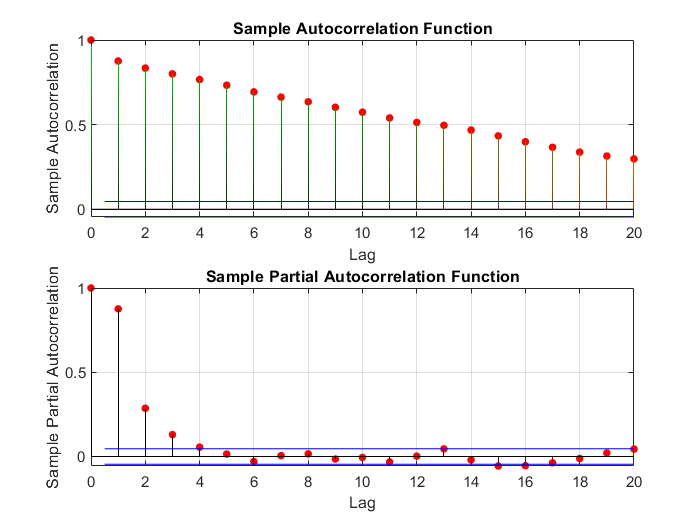

%plotting ACF and PACF of the data

subplot(2,1,1) 
autocorr(Train)%ACF of Radon Train data
subplot(2,1,2)
parcorr(Train)%PACF of Radon Train data

%we apply ARIMA(1,0,1)

model=arima(1,0,1)%declaring the model 

model =   arima with properties:

     Description: "ARIMA(1,0,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 0
               Q: 1
        Constant: NaN
              AR: {NaN} at lag [1]
             SAR: {}
              MA: {NaN} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

# Note: the data is stationary, so lets choose to apply the ARIMA(1,0,1) on Train data first

%applying the model on my Training data
fit=estimate(model,Train)

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant       1.013        0.25377        3.9919       6.5534e-05
    AR{1}        0.95552      0.0066097        144.56                0
    MA{1}       -0.38176       0.014238       -26.812      2.3517e-158
    Variance      56.491        0.81612        69.219                0



fit =   arima with properties:

     Description: "ARIMA(1,0,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 0
               Q: 1
        Constant: 1.01303
              AR: {0.955516} at lag [1]
             SAR: {}
              MA: {-0.381757} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 56.4911

Check Goodness of Fit Infer the residuals from the fitted model. Check that the residuals are normally distributed and uncorrelated

res = infer(fit,Train);%this is how to get the residual from the Train Radon data

### % Plotting results

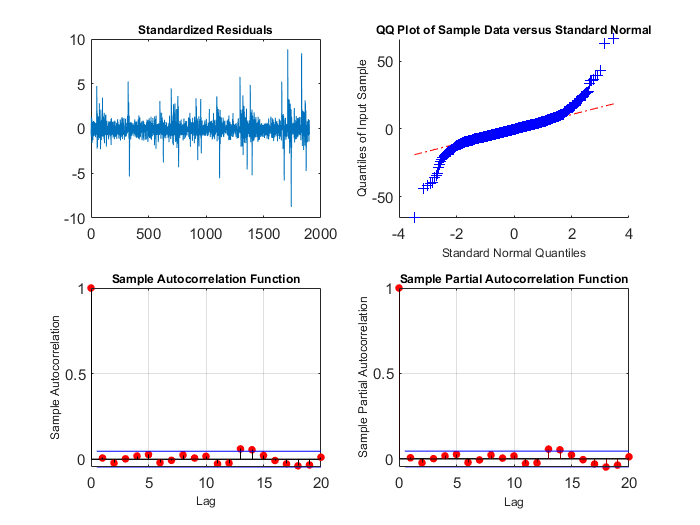

figure 
subplot(2,2,1)%subplots 2,2,1
plot(res./sqrt(fit.Variance))%plotting the standardized residuals
title('Standardized Residuals')%setting the title 
subplot(2,2,2) %second plot
qqplot(res) %plotting the quantiles
subplot(2,2,3) 
autocorr(res) %plotting autocorrelation function of the residual
subplot(2,2,4) 
parcorr(res)%partial autocorrelation function of the residual
hvec = findall(gcf,'Type','axes'); 
set(hvec,'TitleFontSizeMultiplier',0.8,'LabelFontSizeMultiplier',0.8);%adjusting size and font

 %The residual looks reasonable
%  The residuals are reasonably normally distributed and uncorrelated. 

Now Forecasting the results

Generate Forecasts Generate forecasts and approximate 95% forecast intervals for the next 100 or more time steps. 

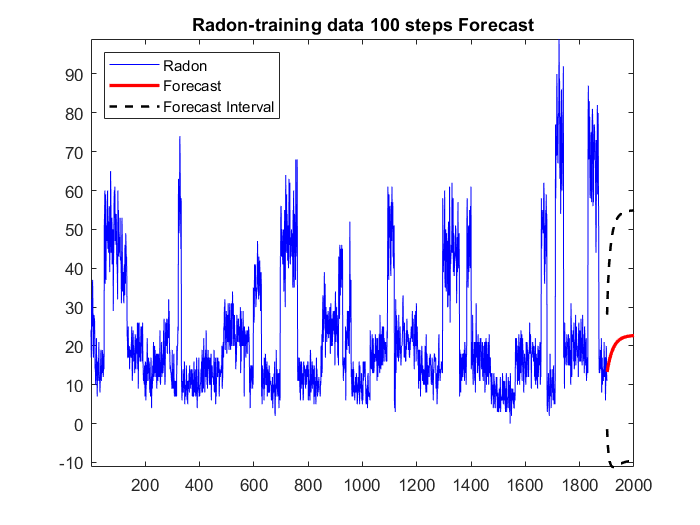

[yF,yMSE] = forecast(fit,100,'Y0',Train);%100 means path
UB = yF + 1.96*sqrt(yMSE); %this is just for upper bound
LB = yF - 1.96*sqrt(yMSE);%this is for lower forecast bound
figure 
%h4 = plot(Date(1:1900),Train,'green');%1:1900 means from begining to end of the train data
h4 = plot(Train,'blue');%1:4000 means from begining to end of the train data

hold on
h5 = plot(1901:2000,yF,'r','LineWidth',2);%1901:2000 from last train value to 100 points further
%h5 = plot(Date(1900:2000),yF,'r','LineWidth',2);%1900:2000 from last train value to 100 points further
%h6 = plot(Date(1900:2000),UB,'k--','LineWidth',1.5);%plotting upper bound for 100 further steps
h6 = plot(1901:2000,UB,'k--','LineWidth',1.5);%plotting upper bound for 100 further steps
plot(1901:2000,LB,'k--','LineWidth',1.5); %plotting the lower bound for 100 
%plot(Date(1900:2000),LB,'k--','LineWidth',1.5); %plotting the lower bound for 100 
legend([h4,h5,h6],'Radon','Forecast','Forecast Interval','Location','Northwest')% 
title('Radon-training data 100 steps Forecast')%setting the title
axis tight
hold off

## **Now lets do the Monte-Carlo and simulate 5 paths and Forecast 300 time steps**

rng default % For reproducibility (I.e we can reproduce thesame result)
number_of_paths=7%number of Monte Carlo simulation Paths

number_of_paths = 7

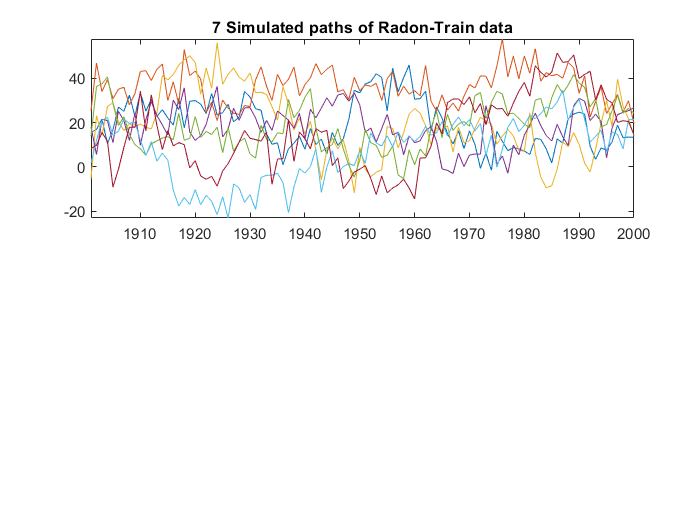

%this below is the simulation code for Monte-Carlo(Please refer to Econometric tool box for details)
[Y E]=simulate(fit,100,'NumPaths',number_of_paths,'Y0',Train);

figure
subplot(2,1,1);
plot(1901:2000,Y)%here I plotted the 100 forecast steps from Last point of radon Train data
title('7 Simulated paths of Radon-Train data')
axis tight

### Now lets plot The Radon data With ARIMA Monte-Carlo simulation forecast for 300 paths 

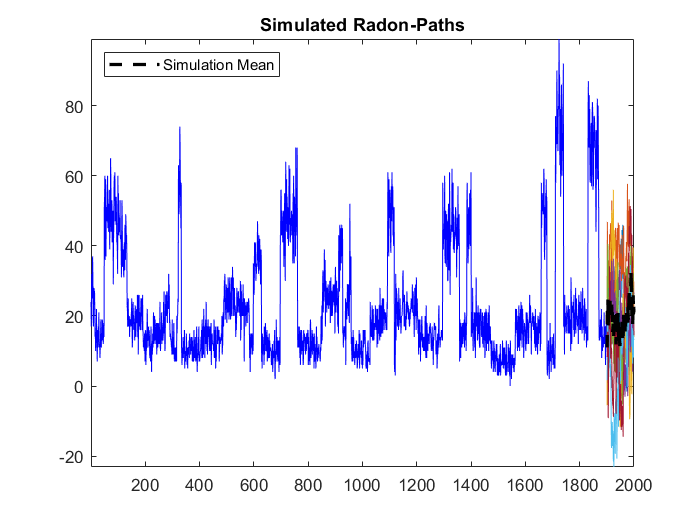


rng('default')% For reproducibility (I.e we can reproduce thesame result)
[Ysim, E] = simulate(fit,100,'NumPaths',number_of_paths,'Y0',Train);%doing the monte Carlo again 100 steps
mn= mean(Ysim,2);%taking the mean simulation path
figure 
plot(Train,'blue')%Now I am plotting the Normal Train Radon data
hold on 
plot(1901:2000,Ysim);%Plotting 100 steps forecast.....(Note: there will be 7 curves because of simulation paths )
axis tight
 h = plot(1901:2000,mn,'k--','LineWidth',2); %plotting the simulation Mean (i.e the mean of Monte-Carlo paths)
 
 title('Simulated Radon-Paths') %setting title
 legend(h,'Simulation Mean','Location','NorthWest')% legend
 hold off

### Let's plot the Monte-carlo forecast with confidence Bounds

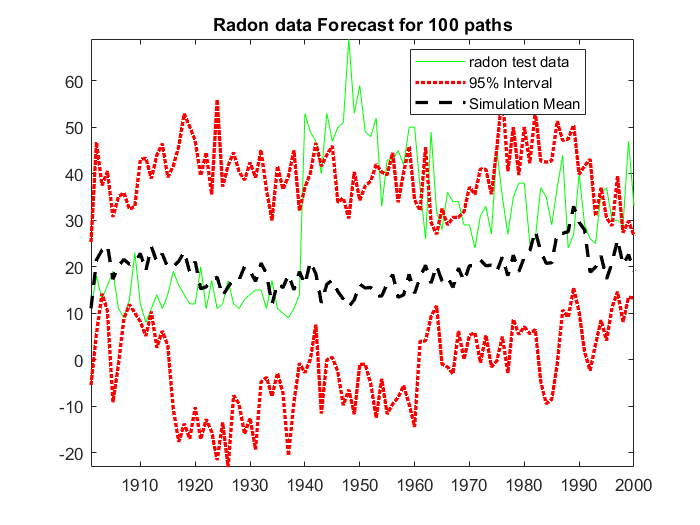


lower = prctile(Y,2.5,2);%lower bounds
upper = prctile(Y,97.5,2);%upper bounds
mn = mean(Y,2);%Monte carlo mean from the simulation path

figure
plot(1901:2000,test(1:100),'green')%here we are plotting the test but only 300 steps
legend("Radon test data")
axis tight
hold on
plot(1901:2000,lower,'r:','LineWidth',2);%plotting the lower bounds
axis tight
plot(1901:2000,mn,'k--','LineWidth',2);%Plotting the monte Carlo simulation mean
plot(1901:2000,upper,'r:','LineWidth',2)%plotting the upper bounds
axis tight
legend('radon test data','95% Interval','Simulation Mean','Location','best')
title('Radon data Forecast for 100 paths')
hold off

[yF,yMSE] = forecast(fit,100,'Y0',Train);%100 means path
UB = yF + 1.96*sqrt(yMSE); %this is just for upper bound
LB = yF - 1.96*sqrt(yMSE);%this is for lower forecast bound
figure 

h4 = plot(Train,'blue');%1:4000 means from begining to end of the train data

hold on
h5 = plot(1901:2000,yF,'r','LineWidth',2);%1901:2000 from last train value to 300 points further

h6 = plot(1901:2000,UB,'k--','LineWidth',1.5);%plotting upper bound for 100 further steps
h7=plot(1901:2000,test(1:100),'green')%here we are plotting the test but only 100 steps

h7 =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


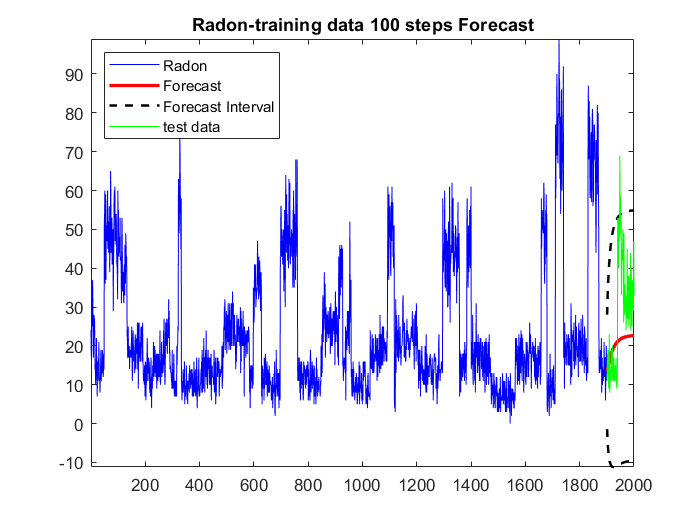

plot(1901:2000,LB,'k--','LineWidth',1.5); %plotting the lower bound for 100 
legend([h4,h5,h6,h7],'Radon','Forecast','Forecast Interval','test data','Location','Northwest')% 
title('Radon-training data 100 steps Forecast')%setting the title
axis tight
hold off


rng('default')% For reproducibility (I.e we can reproduce thesame result)
[Ysim, E] = simulate(fit,100,'NumPaths',number_of_paths,'Y0',Train);%doing the monte Carlo again 100 steps
mn= mean(Ysim,2);%taking the mean simulation path
figure 
plot(Train,'blue')%Now I am plotting the Normal Train Radon data
hold on 
plot(1901:2000,Ysim);%Plotting 100 steps forecast.....(Note: there will be 7 curves because of simulation paths )
axis tight
 h = plot(1901:2000,mn,'k--','LineWidth',2); %plotting the simulation Mean (i.e the mean of Monte-Carlo paths)
 h2=plot(1901:2000,test(1:100),'green')%here we are plotting the test but only 100 steps

h2 =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


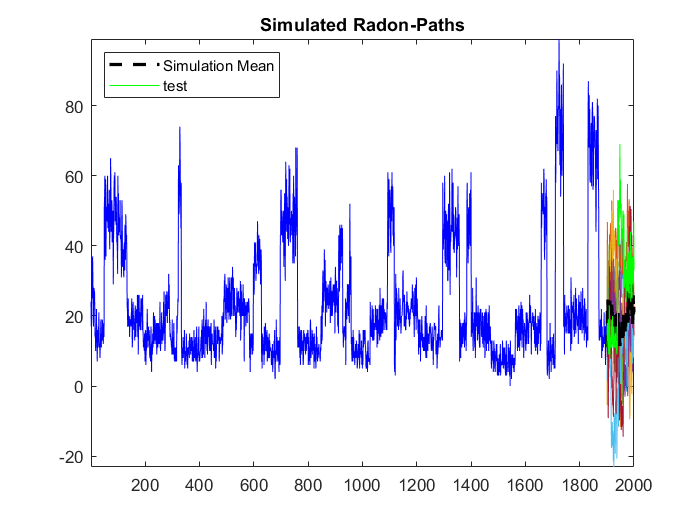

 title('Simulated Radon-Paths') %setting title
 legend([h h2],'Simulation Mean','test','Location','NorthWest')% lege